# **Problem E8.8**

syms x1 x2 real
X = [x1; x2];
f = 0.5*X'*[3 -2;-2 0]*X + [4 4]*X + 2;

## i.

g = gradient(f, X)

$$g = \left(\begin{array}{c} 3\,x_{1}-2\,x_{2}+4\\ 4-2\,x_{1} \end{array}\right)$$

h = hessian(f, X)

$$h = \left(\begin{array}{cc} 3 & -2\\ -2 & 0 \end{array}\right)$$

## ii.

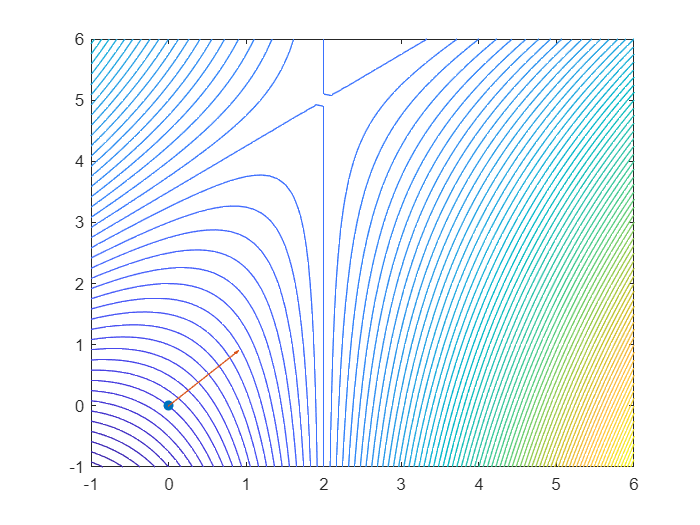

fcontour(f, [-1 6 -1 6], 'LevelStep', 1)
hold on
scatter(0, 0, "filled")
quiver(0, 0, 1, 1)
hold off

## iii.

We will use the formulation presented in the textbook:


$$\textrm{directional}\;\textrm{derivative}\;\textrm{of}\;\left(F\right)\;\;\textrm{at}\;x_0 \;\textrm{in}\;\textrm{direction}\;\left(p\right):\frac{\;p^T \;\nabla F\left(x\right)}{||p||}\;$$


p = [1; 1];
x_0 = [0; 0];
dirderiv = (p'*subs(g,[x1; x2], x_0))/norm(p)

$$dirderiv = 4\,\sqrt{2}$$

## iv.

Indeed, the vector ${\left\lbrack \begin{array}{cc}
1 & \;1
\end{array}\right\rbrack }^T$ is not tangent to the contours at $x_{0\;}$ (as displayed above) and therefore the directional derivative is non-zero.